Lecture 13 secant root, convergences

addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Root Finding'))

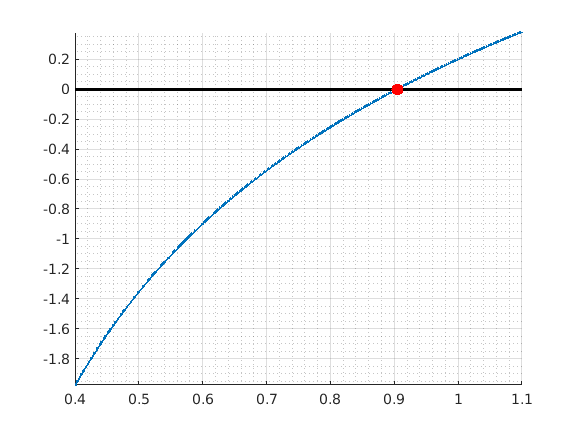

% Example: estimate sin(x) - cot(x)  = 0 to 
% 6 decimal places between 0.5 and 1

f = @(x) sin(x) - cot(x);
plotRoot(f, 0.4, 1.1)

n = 6, nMax = 21, solution = 0.9045569


ans =    0.904556894302383


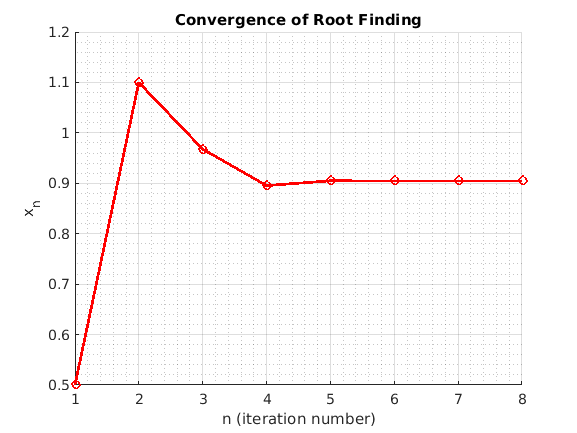

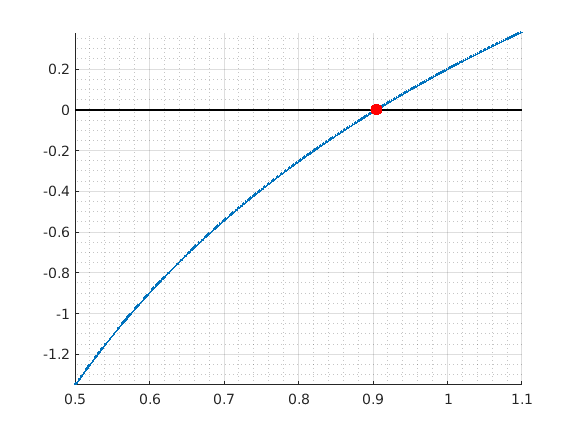

secantP(f, 0.5, 1.1, 6)

Bisection errors (4.45, 4.55)

n = 47, nMax = 47, solution = 4.493409457909064


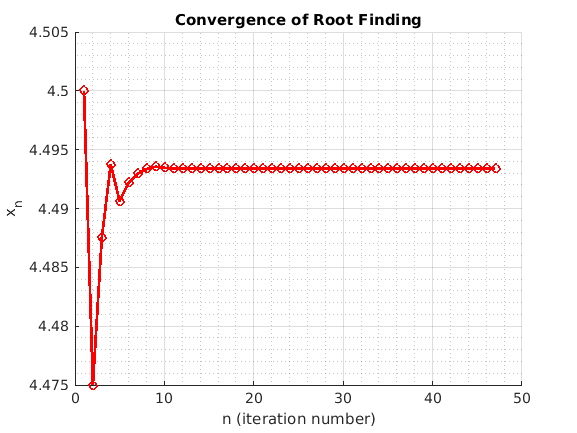

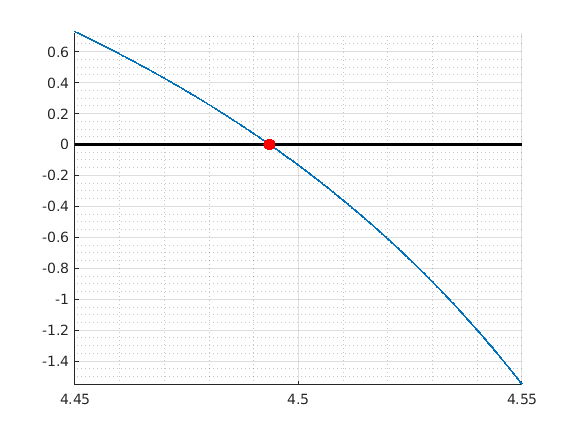

f = @(x) x - tan(x);
[~,x] = bisectE(f, 4.45, 4.55); 

log error slopes = 
  -1.106190058676805
   2.511435723934048
  -0.736313464645798
  -0.391952908693477
   1.238257494496575
   2.132422167554469
  -0.489554805840416
  -1.048286240953229
   3.257318892703729
  -0.801976383642828
  -0.256857590554458
   1.088103903192702
   1.218188036133598
   1.905465958522636
  -0.314950342049800
  -2.508469086335942
   0.212387412566701
   5.287169239674741
  -0.463716480055381
  -1.681007070053982
   0.803985181216117
   0.067858541385236
  46.205582993467935
  -0.778351435224780
  -0.301223055685784
   1.132050376875014
   1.374273008179518
   1.500492368583631
  -0.516286680510470
  -1.281326457974502
   1.590018606604647
  -0.549269179507858
  -1.081414401937082
   2.770787533408842
  -0.763732416038274
  -0.330344396092473
   1.166250194830176
   1.540584004757271
   0.428017476135790
   1.558168323464312
   0.356258246467179
   4.783271061516878
  -0.430676558073393
  -1.000000000000000
                 Inf



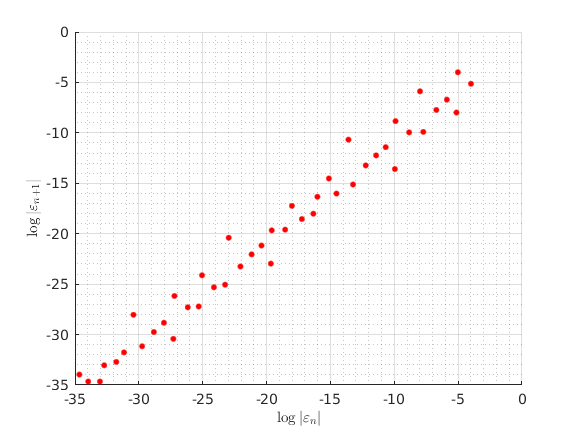

plotLogError(x)% weird slopes! should be c = 0.5

n = 46, nMax = 47, solution = 4.299999999999999


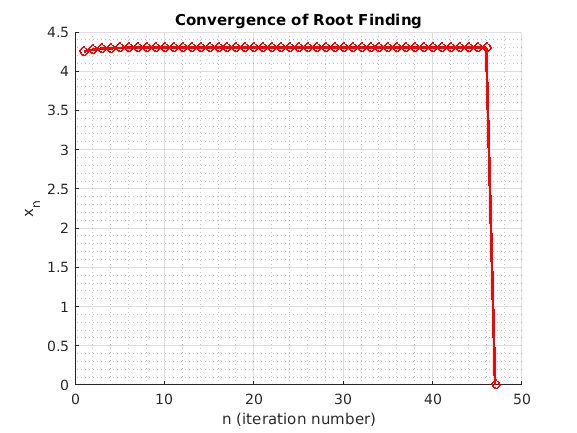

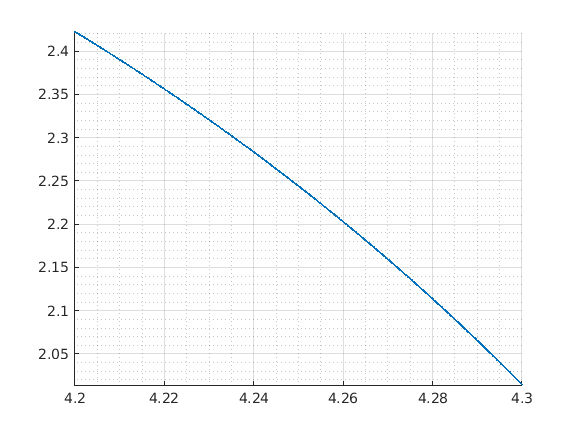

[~,x] = bisectE(f, 4.2, 4.3);

log error slopes = 
   0.497809145581996
   0.498907235619137
   0.499454280751231
   0.499727305766837
   0.499863694188619
   0.499931857413796
   0.499965931290788
   0.499982966288995
   0.499991483300404
   0.499995741690101
   0.499997870866025
   0.499998935477364
   0.499999467581116
   0.499999733751166
   0.499999867344811
   0.499999933672388
   0.499999966210457
   0.499999979976566
   0.500000005005859
   0.499999979976565
   0.500000000000000
   0.499999919906258
   0.500000320375018
   0.499999679625187
   0.499999679624982
   0.500000640750447
   0.500000000000000
   0.500005125997006
   0.499984622166634
   0.500000000000000
   0.500020504408448
   0.500041007135242
   0.499917992455306
   0.499671916010499
   0.500984898227183
   0.499344692005242
   0.498687664041995
   0.500000000000000
   0.515789473684211
   0.489795918367347
   0.458333333333333
   0.454545454545455
   0.800000000000000
   0.500000000000000
                -Inf



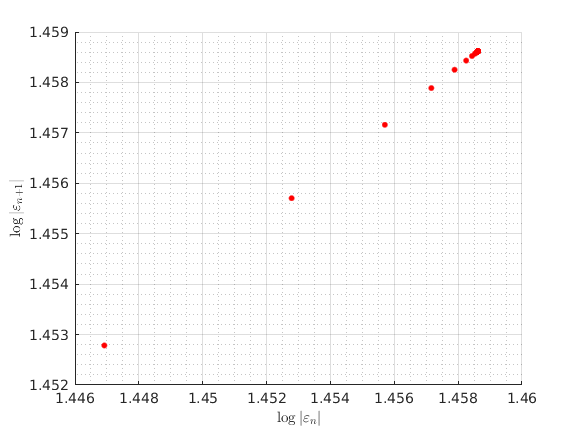

plotLogError(x) % slopes now 0.5

Fixed point convergence with EPS

n = 13, nMax = 300, solution = 4.493409457909064


ans =    4.493409457909064


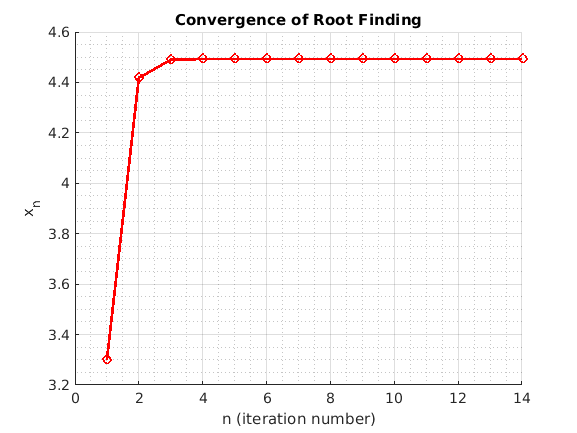

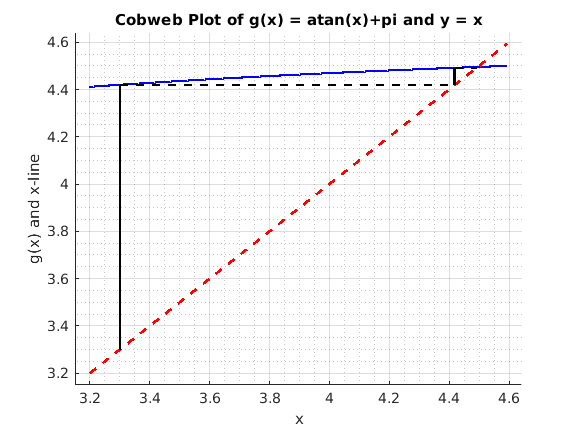

f = @(x) x - tan(x);
g = @(x) atan(x) + pi;
% note atan(x) outpits [-pi/2, pi/2] but we
% want output to be in [pi/2, 3pi/2]
fixedPointE(g, 3.3)

Errors for fixed point x0 = 4.55

[~,x] = fixedPointE(g, 4.55);
plotLogError(x) % slopes are close to 1
% for fixed point, consistent with theory
% that it always converges linearly. 

Errors fixed point x0 = 4.2

n = 12, nMax = 300, solution = 4.493409457909064


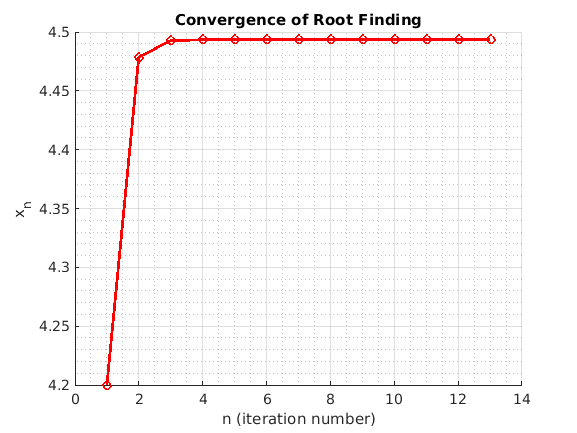

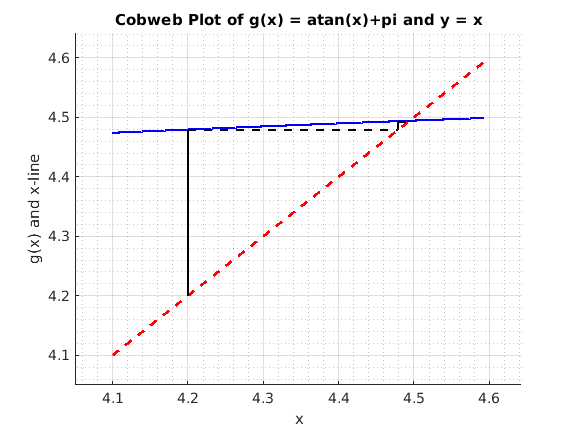

[~,x] = fixedPointE(g, 4.2);

log error slopes = 
   1.020414788355808
   1.000979244338311
   1.000046247535757
   1.000002183247235
   1.000000095698816
   0.999998588900226
   0.999989309928778
   1.000155366412152
   1.005801241649885
   0.958564167060589
                 Inf



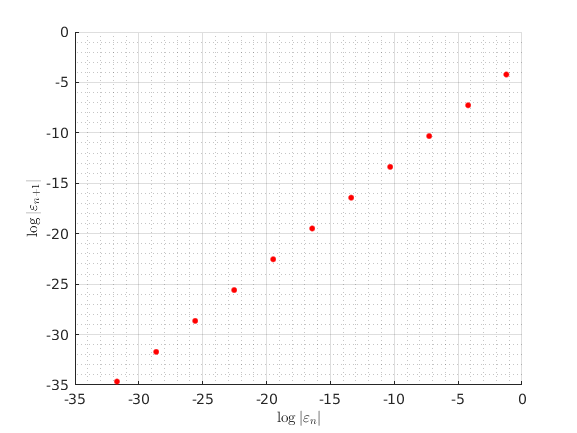

plotLogError(x) 

Newton with EPS

n = 6, nMax = 100, solution = 4.493409457909064


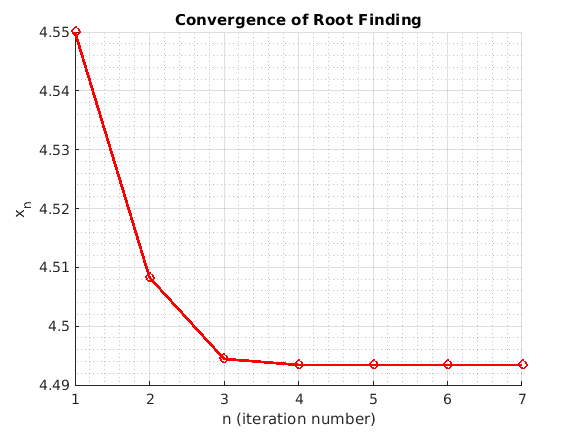

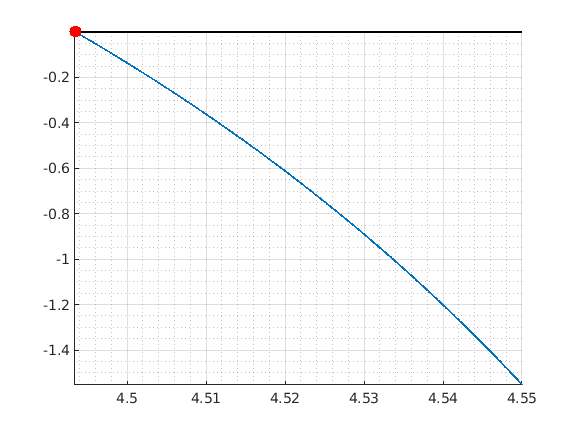

f = @(x) x - tan(x);
fd = @(x) 1 - sec(x)^2;
[~, x] = newtonE(f, fd, 4.55);

Errors newton = 4.55

n = 7 iterations
log error slopes = 
   1.992291040357187
   1.998514338529832
   1.999942286656926
                 Inf
                 NaN



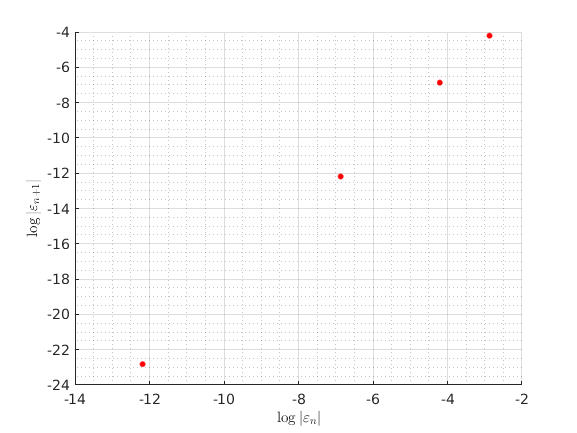

plotLogError(x) % to the left, the errors get

% so small that we have numerical errors in 
% the estimation so results are skewed, look
% mostly to the right. 

% NOTE: slopes close to 2, consistent with theory
%that gamma = 2, so quadratic convergence. 

Errors newton x0 = 4.2

n = 100, nMax = 100, solution = 3345487426508330420614716998702903861315748243701760.000000000000000


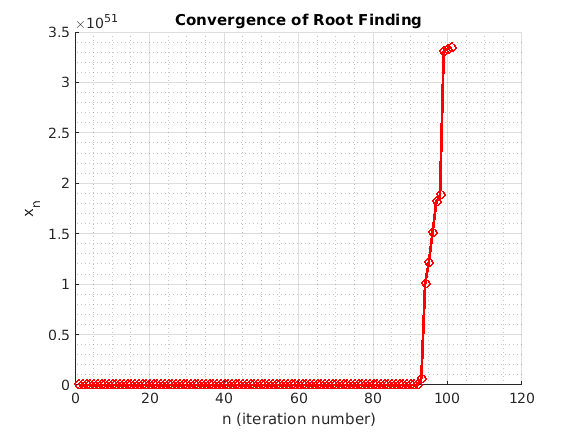

[~, x] = newtonE(f, fd, 4.2); % get divergence

log error slopes = 
   1.0e+04 *

                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN
                 NaN


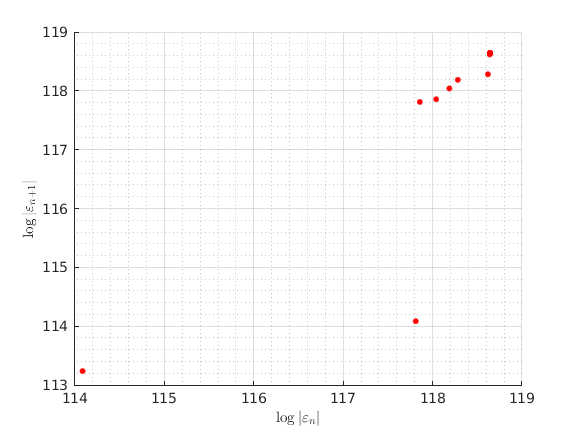

plotLogError(x)

Secant errors (4.45, 4.55)

n = 8, nMax = 47, solution = 4.493409457909064


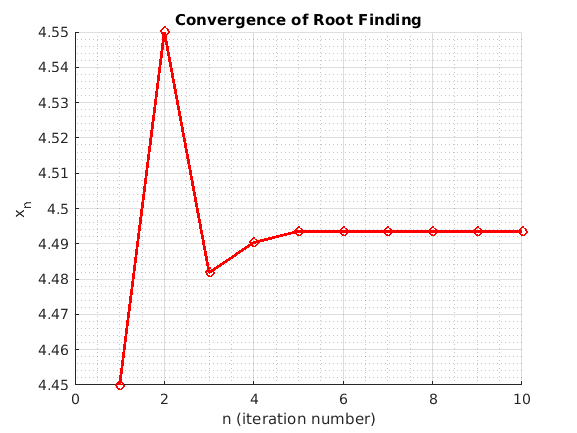

[~,x] = secantE(f, 4.45, 4.55);

log error slopes = 
  -5.995351099853883
   0.835397463983840
   2.190026999640759
   1.457221518292675
   1.686344391896989
   1.594345467994876
                 Inf
                 NaN



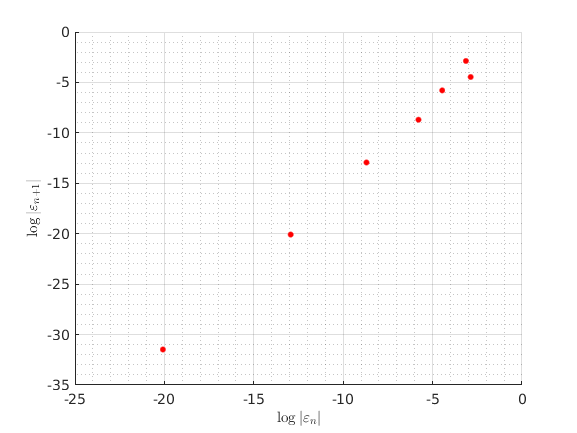

plotLogError(x) % some noise at beginning

% becauase of first input user data, then
%slopes go to 1.6 something (golden ratio)

Secant errors (4.2, 4.3)

n = 46, nMax = 47, solution = 0.000089550396922


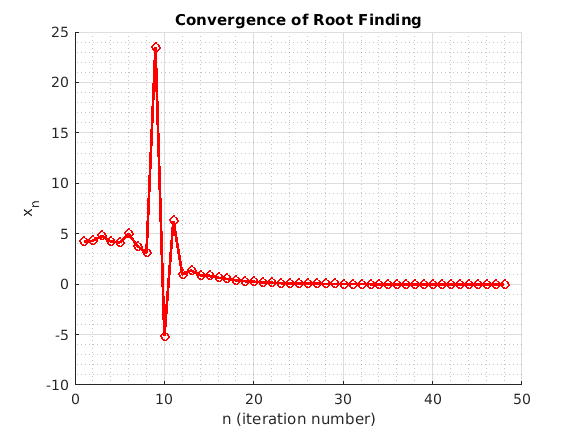

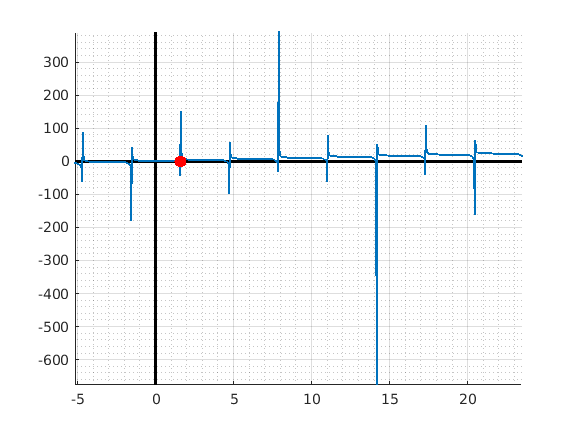

[~,x] = secantE(f, 4.2, 4.3); % some disparity later on. 

log error slopes = 
   4.617957809863549
  -1.142292403796286
   0.167849936053419
  -8.889383261599278
  -1.499448142800366
   0.706798440556858
 -10.305169780390099
  -0.749092193486561
  -0.129790115791116
  -9.520432071207120
  -0.176369303794302
  -1.236068095495673
   0.169547493880632
   3.854170324099704
   0.804621894246070
   1.227575419845742
   0.991346773958310
   1.046106542190170
   1.007207786638013
   1.011664213749746
   1.003957992194051
   1.003496058278209
   1.001767937533509
   1.001420247886914
   1.001080758073997
   1.001080997676063
   1.001192142661467
   1.001459411667788
   1.001861216597302
   1.002430746108826
   1.003206247707362
   1.004252135770236
   1.005657267708473
   1.007547078914684
   1.010097371524617
   1.013558335075953
   1.018292921583387
   1.024842557386318
   1.034045335972267
   1.047264256801956
   1.066868491616574
   1.097373038660331
   1.148612775229102
   1.247076964704908
   1.499999989024500
                 Inf



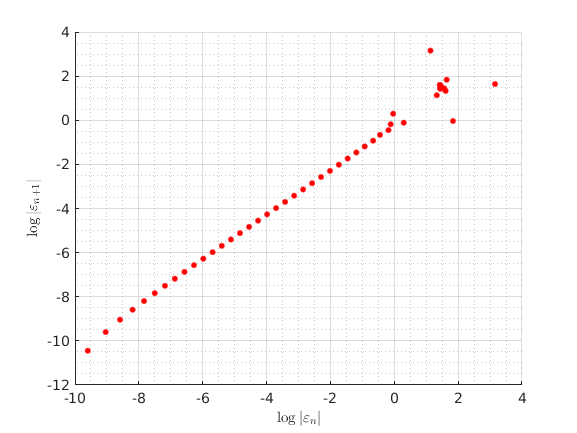

plotLogError(x)